# Simulating Stochastic Transition Scenarios

This live script computes the deterministic and stochastic transition dynamics of a climate-economic model solved with Dynare’s extended-path algorithm.

We first initialize the model, construct the Business-As-Usual transition, and generate a sequence of random shocks consistent with the model’s covariance structure.

The script then applies the same shocks to a net-zero policy scenario, yielding stochastic paths around the Paris-Agreement transition.

Both deterministic and stochastic trajectories are compared to assess the macroeconomic and climate implications of alternative carbon policies.

The final section contrasts the stochastic BAU and net-zero economies to quantify how uncertainty interacts with climate mitigation.

## I. Initialization of the path of the model

We start by loading the model using Dynare:

dynare model_file

Starting Dynare (version 6.4).
Calling Dynare with arguments: none
Starting preprocessing of the model file ... 
Found 20 equation(s). 
Evaluating expressions... 
Computing static model derivatives (order 1). 
Normalizing the static model... 
Normalization failed with cutoff, trying symbolic normalization... 
Finding the optimal block decomposition of the static model... 
11 block(s) found: 
  10 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 7 feedback variable(s). 
Computing dynamic model derivatives (order 2). 
Normalizing the dynamic model... 
Finding the optimal block decomposition of the dynamic model... 
4 block(s) found: 
  3 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 4 feedback variable(s). 
Preprocessing complete


STEADY-STATE RESULTS:

Z       		 23.3662
L       		 10.48
gZ      		 0
SIG     		 0
THETA1  		 0
delthet 		 0
M       		 2790.93
y       		 0.957955
c       		 0.957955
r       		 1.00503
w       		 0.93576
h       		 1.02372
mu      		 0
d       		 0.93576
tau     		 0
E       		 0
T       		 6.41914
tau_USD 		 0
welfare 		 -179.564
s_a     		 1
Total computing time : 0h00m00s
Note: 1 warning(s) encountered in the preprocessor
Note: warning(s) encountered in MATLAB/Octave code



% solve the path for business as usual
[y_guess,oo_,M_]		= EP_paths_init(oo_,M_,options_,exo_init_ts);
[y_bau] 				= EP_deterministic_path(y_guess,exo_init_ts,oo_,M_,options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 6.01356,	 time = 0.161
Iter: 2,	 err. = 2.27374e-13,	 time = 0.075

Total time of simulation: 0.296.
--------------------------------------------------------



## II. Computing the stochastic transition scenario

### A. Generate random productivity shocks

To simulate uncertainty around the deterministic transition, we now construct a sequence of stochastic shocks. We select a time window of 500 periods starting after the initial date of the exogenous series. For each shock classified as a surprise shock, we draw innovations from a multivariate normal distribution consistent with the covariance matrix `M_.Sigma_e`. These innovations are then merged into the original exogenous series to form a full `dseries` object containing both deterministic and stochastic components.

The resulting object `innovations_ts` will be used to compute stochastic transition paths around the deterministic scenario.

%% Introducing random shocks
% Define the time window for stochastic simulations
stochastic_dates = exo_init_ts.dates(2) : (exo_init_ts.dates(2) + 500);
% Extract baseline deterministic exogenous data
innovations = exo_init_ts(stochastic_dates).data;
% Identify surprise shocks to be replaced with randomness
idS = find(options_.surprise_shocks);
% Generate multivariate Gaussian shocks consistent with Sigma_e
innovations(:, idS) = randn([length(stochastic_dates), length(idS)]) * ...
                      chol(M_.Sigma_e(idS, idS));
% Build a new dseries object containing the random innovations
innovations_ts = exo_init_ts;
innovations_ts = ds_leftmerge(innovations_ts, ...
                              dseries(innovations, stochastic_dates(1), M_.exo_names));
% Display the resulting series of stochastic exogenous shocks
innovations_ts

 
innovations_ts is a dseries object:
 
       | e_a        | e_tau
1984Q4 | 0          | 0    
1985Q1 | 0.0037637  | 0    
1985Q2 | 0.012837   | 0    
1985Q3 | -0.015812  | 0    
1985Q4 | 0.0060352  | 0    
1986Q1 | 0.0022314  | 0    
1986Q2 | -0.0091538 | 0    
1986Q3 | -0.0030351 | 0    
1986Q4 | 0.0023984  | 0    
1987Q1 | 0.025049   | 0    
       |            |      
2732Q1 | 0          | 1    
2732Q2 | 0          | 1    
2732Q3 | 0          | 1    
2732Q4 | 0          | 1    
2733Q1 | 0          | 1    
2733Q2 | 0          | 1    
2733Q3 | 0          | 1    
2733Q4 | 0          | 1    
2734Q1 | 0          | 1    
2734Q2 | 0          | 1    
2734Q3 | 0          | 1    
 


### B. Feed shocks into a transition scenario

We now construct a full transition scenario for the net-zero policy, combining both deterministic dynamics and stochastic shocks.

First, we update the terminal state of the model for a given value of the policy parameter `varphi = 1`, which defines the net-zero transition in the long run. Using these updated structures, we compute the corresponding deterministic transition path, taking as given the exogenous series (including the tax path and the deterministic component of shocks).

Second, we superimpose the random innovations stored in `innovations_ts` and use `EP_stochastic_path` to generate the stochastic transition `sto_nz0`. This path describes how the economy fluctuates around the deterministic net-zero trajectory when surprise shocks are realized over the horizon `stochastic_dates`.

% SCENARIO: Transition
% Update parameter in implementation of carbon tax
[det_nz0,oo_nz0,M_nz0]    = update_terminal_state('varphi',1,oo_,M_,exo_init_ts,y_guess);
% Step 1: Compute the deterministic path
[det_nz0] 		= EP_deterministic_path(det_nz0,innovations_ts,oo_nz0,M_nz0,options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 6.01356,	 time = 0.072
Iter: 2,	 err. = 0.432327,	 time = 0.068
Iter: 3,	 err. = 0.0033911,	 time = 0.062
Iter: 4,	 err. = 4.74316e-07,	 time = 0.06

Total time of simulation: 0.361.
--------------------------------------------------------



% Step 2: Compute the stochastic path
[sto_nz0]   	= EP_stochastic_path(det_nz0,innovations_ts,oo_nz0,M_nz0,options_,stochastic_dates);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.00376367,	 time = 0.002
Iter: 2,	 err. = 2.04514e-05,	 time = 0.002
Iter: 3,	 err. = 2.14868e-11,	 time = 0.003

Total time of simulation: 0.014.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.0755493,	 time = 0.002
Iter: 2,	 err. = 0.000234565,	 time = 0.002
Iter: 3,	 err. = 2.80284e-09,	 time = 0.002

Total time of simulation: 0.01.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.334351,	 time = 0.002
Iter: 2,	 err. = 0.000350645,	 time = 0.002
Iter: 3,	 err. = 6.46128e-09,	 time = 0.004

Total time of simulation: 0.01.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.0138258,	

### C. Plot the deterministic and the stochastic path

Next we simply compare the two paths.

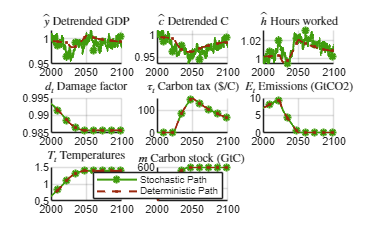

% PLOT FIGURE
nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M');
nn=size(varnames,1);
figure('Name','Figure 4: Stochastic economy');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),sto_nz0,'*-','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(sto_nz0,1))
	plotds(varnames(i1,:),det_nz0,'.--','Color',[156, 40, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(det_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([2000 2100])
end
legend('Stochastic Path','Deterministic Path')

## III. Stochastic simulations: Business-As-Usual vs Paris Agreement

Let us now consider the stochastic dynamics of the economy under two policy regimes:

- a Business-As-Usual (BAU) scenario, where climate policy follows the baseline carbon tax path `exo_init_ts`,

- a Paris-Agreement scenario, where the economy is steered toward net-zero emissions.

For each regime, we first compute the deterministic transition and then superimpose the same sequence of stochastic shocks `innovations_ts`. The resulting paths `sto_bau` and `sto_nz0` describe how macroeconomic and climate variables co-move under uncertainty. The figure below compares the two stochastic economies over the period 2000–2100.

% SCENARIO: Business as usual
% Step 1: Compute the deterministic path
[det_bau] 		= EP_deterministic_path(y_guess,exo_init_ts,oo_,M_,options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 6.01356,	 time = 0.062
Iter: 2,	 err. = 2.27374e-13,	 time = 0.06

Total time of simulation: 0.152.
--------------------------------------------------------



% Step 2: Compute the stochastic path
[sto_bau]   	= EP_stochastic_path(det_bau,innovations_ts,oo_,M_,options_,stochastic_dates);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.00376367,	 time = 0.002
Iter: 2,	 err. = 2.04514e-05,	 time = 0.002
Iter: 3,	 err. = 2.14868e-11,	 time = 0.002

Total time of simulation: 0.016.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.0755493,	 time = 0.003
Iter: 2,	 err. = 0.000234565,	 time = 0.002
Iter: 3,	 err. = 2.80295e-09,	 time = 0.002

Total time of simulation: 0.01.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.334351,	 time = 0.002
Iter: 2,	 err. = 0.000350645,	 time = 0.003
Iter: 3,	 err. = 6.46128e-09,	 time = 0.003

Total time of simulation: 0.01.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.0138258,	

and then plot the result.

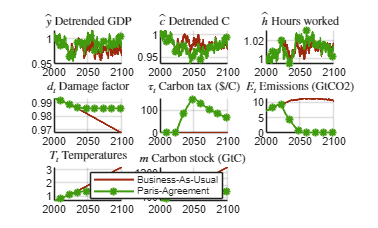

% PLOT FIGURE
nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M');
nn=size(varnames,1);
figure('Name','Figure 5: Stochastic economy');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),sto_bau,'Color',[156, 40, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(sto_bau,1))
	plotds(varnames(i1,:),sto_nz0,'*-','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(sto_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([2000 2100])
end
legend('Business-As-Usual','Paris-Agreement')